# **Project:**

## **TLT Level 2:**

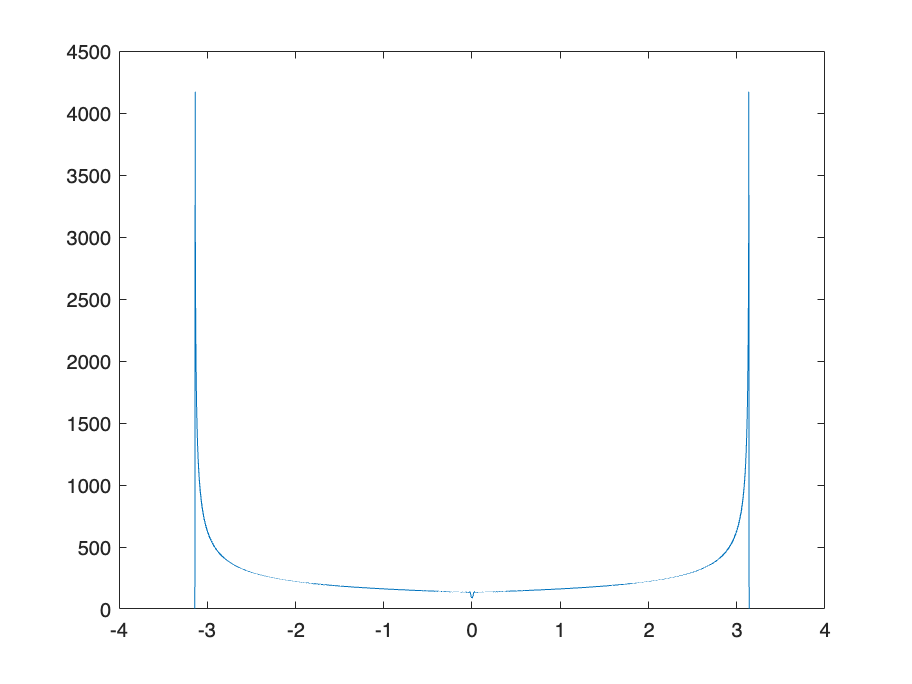

Fs = 16000; %sampling rate required

input = audioread("chirp.wav");
len = length(input);

x1 = 1:len;
theta = linspace(-pi,pi,len); %x-axis

%frequency spectrum of input
x1 = fft(input, len);
plot(theta, abs(x1));

f7 =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


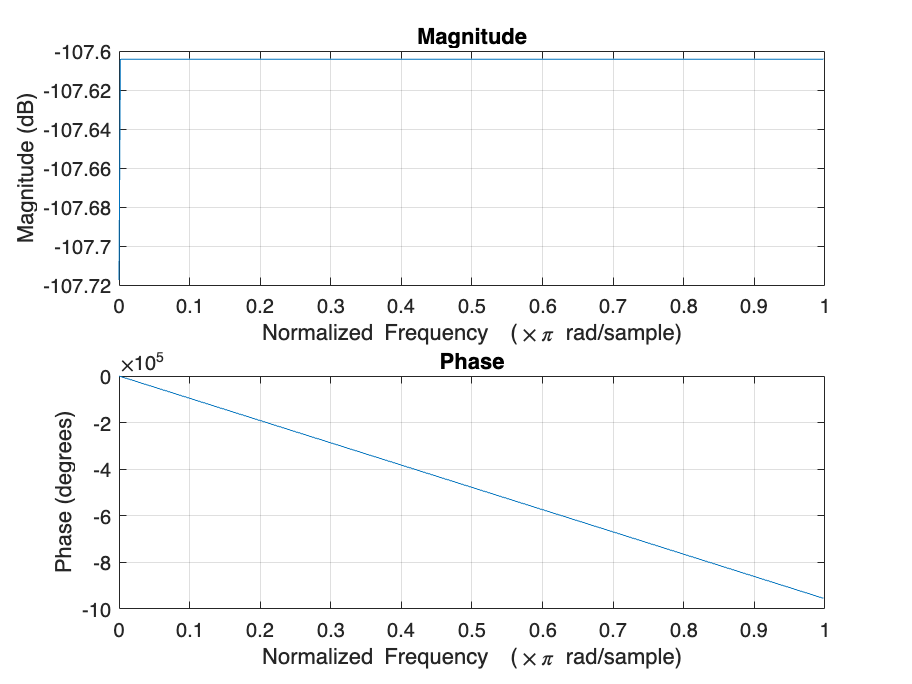


%bandpass filters for each channel
fi1 = fir1(len-1, [0.0000001,0.2], "bandpass");
fi2 = fir1(len-1, [0.2,0.4], "bandpass");
fi3 = fir1(len-1, [0.4,0.6], "bandpass");
fi4 = fir1(len-1, [0.6,0.8], "bandpass");
fi5 = fir1(len-1, [0.8, 0.9999], "bandpass");


%adjustable gains for each channel
gain1 = 58

gain1 = 58

gain2 = 31

gain2 = 31

gain3 = 0

gain3 = 0

gain4 = 71

gain4 = 71

gain5 = 60

gain5 = 60

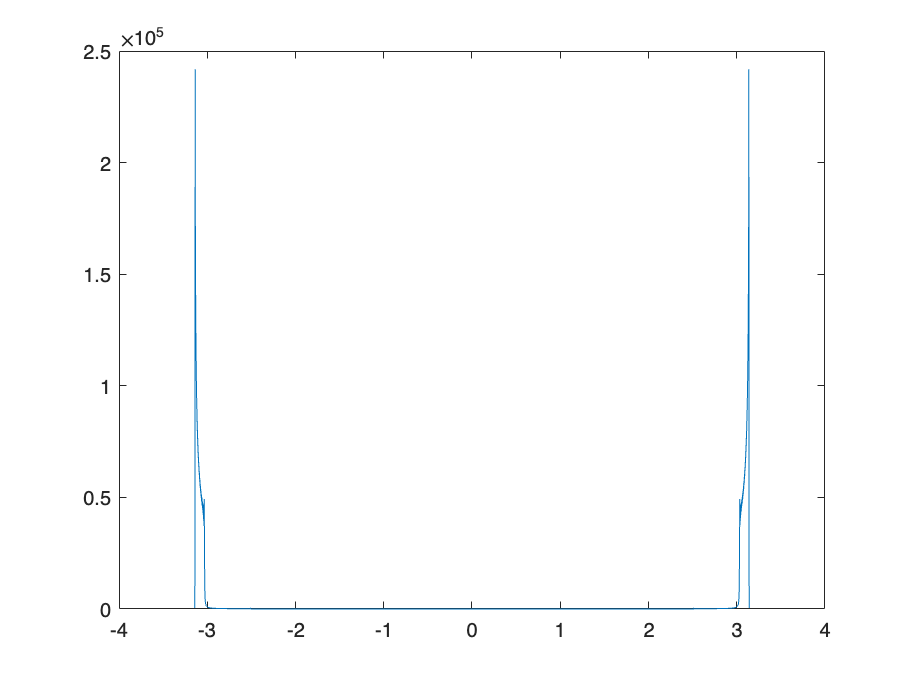


%creating transfer function for the filter
f1 = gain1*filter(fi1, 1 , input);
f2 = gain2*filter(fi2, 1, input);
f3 = gain3*filter(fi3, 1, input);
f4 = gain4*filter(fi4, 1, input);
f5 = gain5*filter(fi5, 1, input);
f_final = f1+f2+f3+f4+f5;

%taking fft of the functions to get freq domain 
w1 = fft(f1, len);
w2 = fft(f2, len);
w3 = fft(f3, len);
w4 = fft(f4, len);
w5 = fft(f5, len);

%frequency response of final output 
w_final = w1+w2+w3+w4+w5;

%plotting magnitude response of filters 
plot(theta,abs(w1));

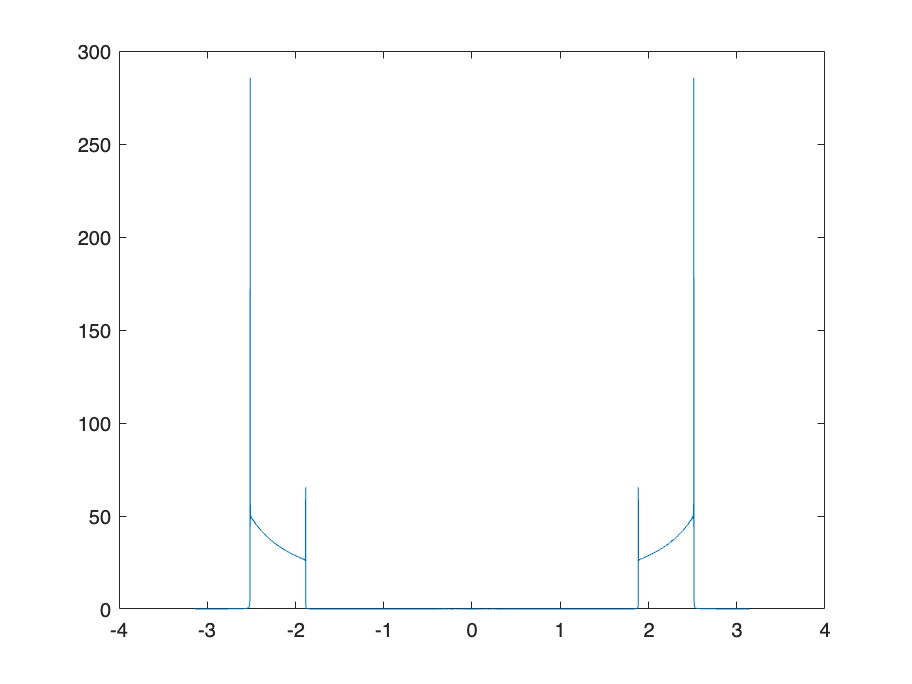

plot(theta,abs(w2));

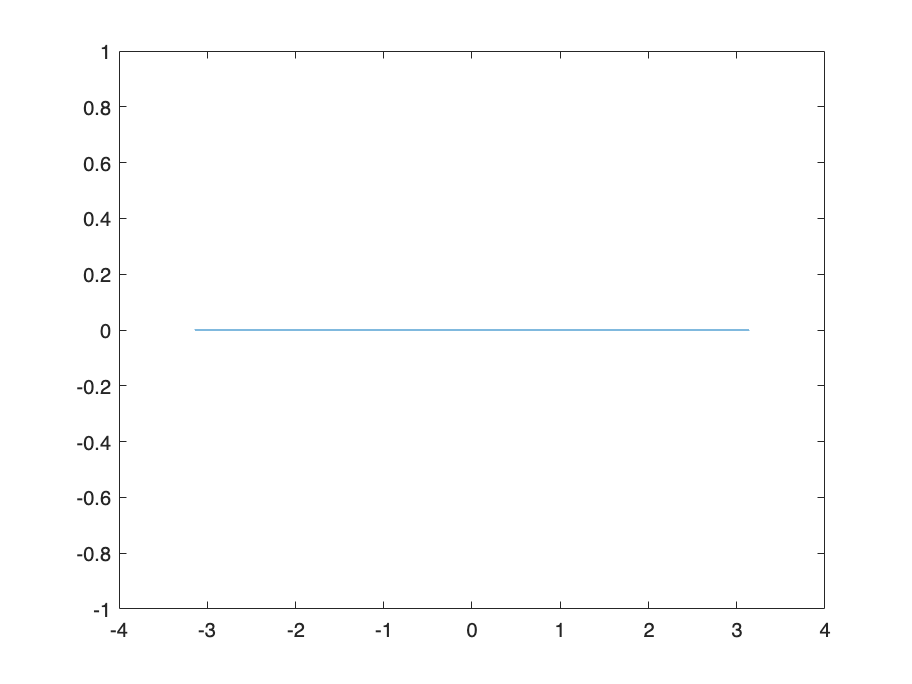

plot(theta,abs(w3));

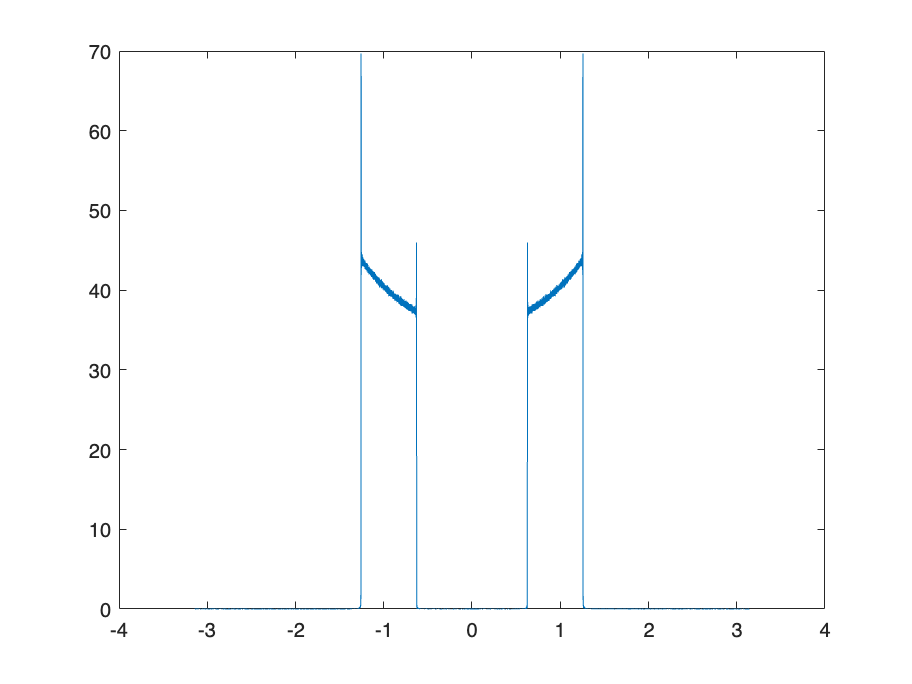

plot(theta,abs(w4));

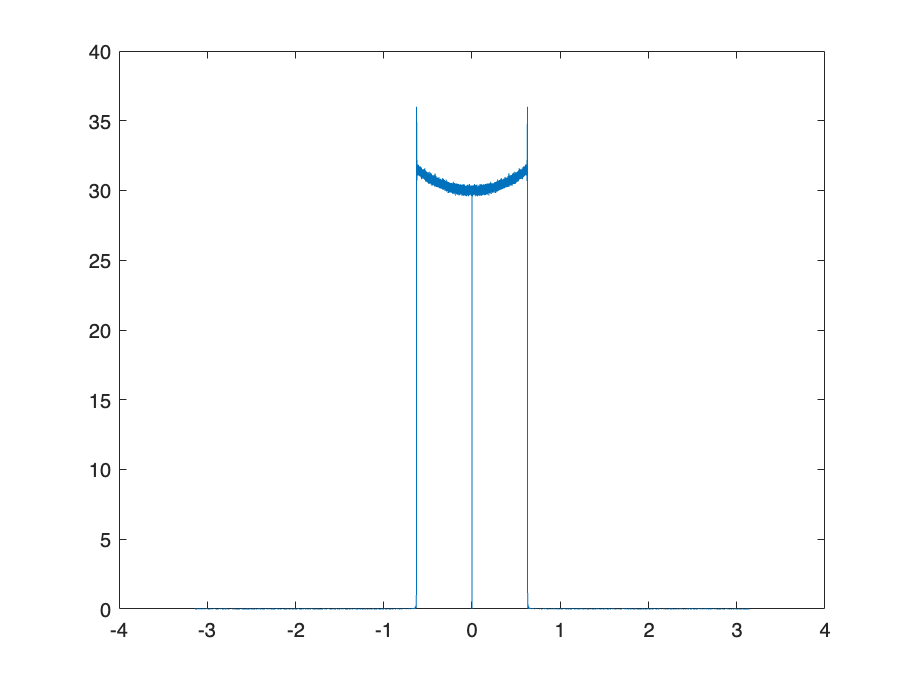

plot(theta,abs(w5));

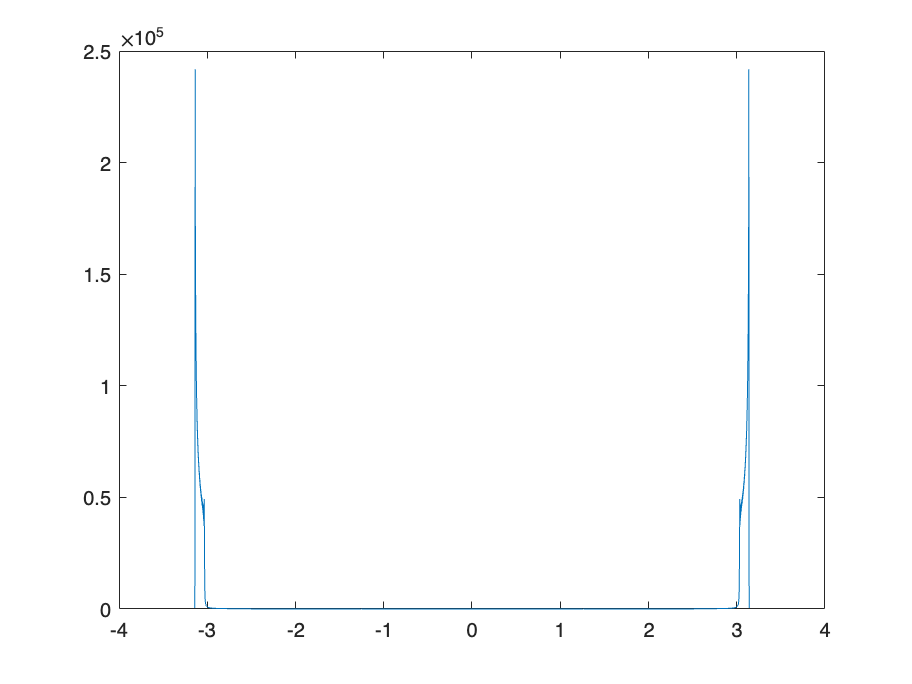

plot(theta, abs(w_final));


%creating files and saving them as a normalised audio file 
output_final = f_final/max(abs(f_final));

audiowrite('output_final.wav', output_final, Fs);


%input sound
sound(input, Fs);

%output sound 
output = audioread('output_final.wav');

output =    -0.0000
         0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


sound(output, Fs);

## **TLT Level 3:**

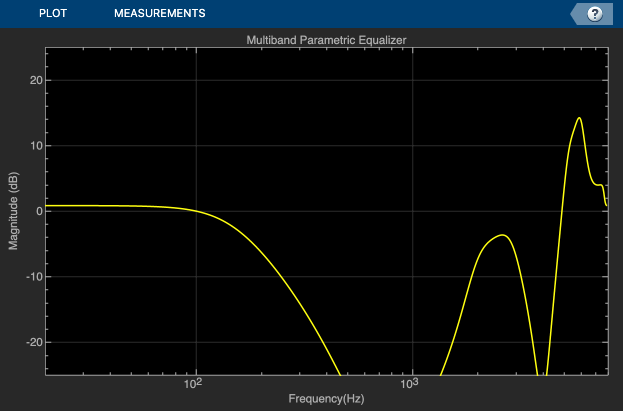

Fs = 16000; %sampling rate required

i = dsp.AudioFileReader("chirp.wav", "PlayCount",2); %input
o = audioDeviceWriter(Fs); %output 

%creates 5 stage equaliser 
equalizer = multibandParametricEQ( ...
    'NumEQBands',5, ... ... %5 channels 
    'Frequencies',[800,2400,4000, 5600, 7199], ... %center frequencies of each channel 
    'QualityFactors',[0.5,1.5,2.5,3.5,4.5], ...%BW = 1600 Hz for each channel
    'PeakGains',[8,-10,7,4,9], ... %gains
    'SampleRate',Fs,...
    'EQOrder', 4); %order of each channel filter. 

parameterTuner(equalizer); %adjusting gains 

graph = timescope(SampleRate= Fs,TimeSpanSource= "auto"); %displaying time signals in real time 

visualize(equalizer); %magnitude response of equalizer in real time

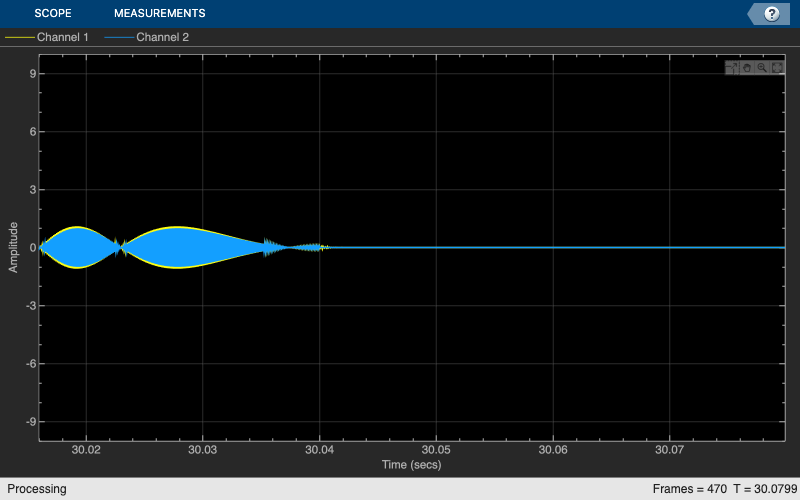

ans = uint32
0

ans = uint32
90112

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
105472

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
2048

ans = uint32
0

ans = uint32
10240

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
8192

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0

ans = uint32
0


%allows adjusting gain in real time 
while ~isDone(i)
    audioIn = i(); %reads in audio input
    audioOut = equalizer(audioIn); %applys changing equaliser gains to input
    o(audioOut) %plays output of equaliser
    graph(audioOut, audioIn); %audioOut=Channel1, audioIN = Channel2
    drawnow limitrate; %limits how quickly you can display audio
end


%release all functions 
release(o);
release(i);
release(equalizer);